# **Wireless Communication**

## `Computer Assignment 2 `

### `Fatemeh Jalili - 810199398`

### **Problem #1 - Maximum Ratio Combining**

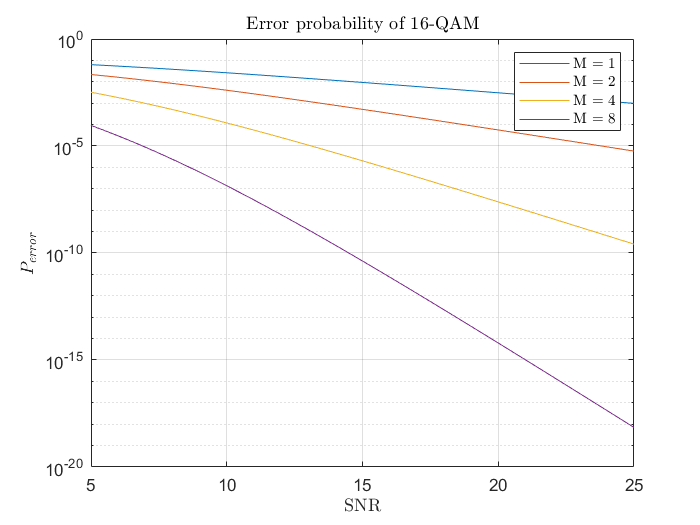

clc, clear, close all;

Mlist = [1 2 4 8];
snrBarList = 5 : 0.2 : 25;
M = 16;

for m = Mlist
    snrIterNum = 1;
    meanPeBitList = zeros(1, length(snrBarList));
    for snrBar = 10 .^ (snrBarList ./ 10)
        intInput = @(snr) (2 * qfunc(sqrt(snr * 3 * log2(M) / (M - 1) )) / log2(M)) ...
            .* (snr .^ (m - 1)) .* exp(-snr ./ snrBar) / (snrBar ^ m * factorial(m - 1));
        meanPeBitList(snrIterNum) = integral(intInput, 0, inf);
        snrIterNum = snrIterNum + 1;
    end
    semilogy(snrBarList, meanPeBitList)
    hold on
end
grid on
title('Error probability of 16-QAM', 'Interpreter', 'latex')
legend('M = 1', 'M = 2', 'M = 4', 'M = 8', 'Interpreter','latex')
ylabel('$P_{error}$', 'Interpreter', 'latex')
xlabel('SNR', 'Interpreter', 'latex')

### **Problem #2 - Time diversity**

**Theoretical:**

clc, clear, close all;

Llist = [1 2 3 4 5];
snrBarList = -10 : 0.5 : 25;
for l = Llist
    snrIterNum = 1;
    meanPeBitList = zeros(1, length(snrBarList));
    for snrBar = 10 .^ (snrBarList ./ 10)
        intInput = @(snr) qfunc(sqrt(snr))...
            .* (snr .^ (l - 1)) .* exp(-snr ./ snrBar) / (snrBar ^ l * factorial(l - 1));
        meanPeBitList(snrIterNum) = integral(intInput, 0, inf);
        snrIterNum = snrIterNum + 1;
    end
    semilogy(snrBarList, meanPeBitList)
    hold on
end

**Simulation:**

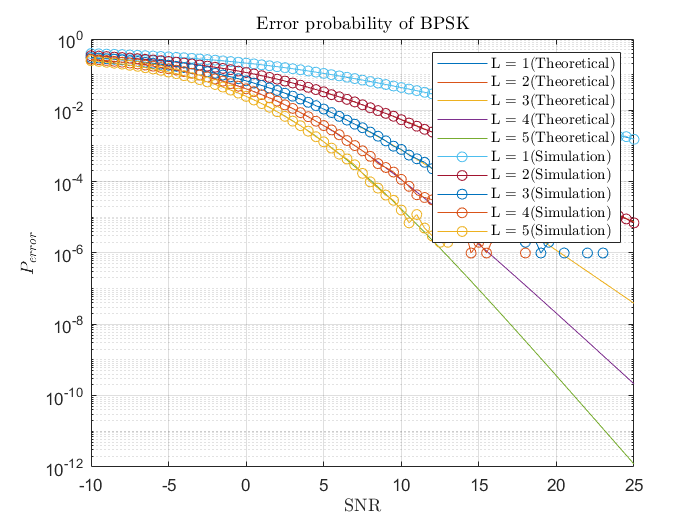

Llist = [1 2 3 4 5];
snrBarList = -10 : 0.5 : 25;
sampleNum = 1e6 ;
N0 = 1;
x = 2 * randi([0 1], 1, sampleNum) - 1;
for l = Llist
    snrIterNum = 1;
    meanPeBitList = zeros(1, length(snrBarList));
    hNormal = randn(l, sampleNum) + 1j * randn(l, sampleNum);
    for snrBar = 10 .^ (snrBarList ./ 10)
        h = sqrt(snrBar / 2) * hNormal;
        w = sqrt(N0) .* (randn(l, sampleNum) + 1j * randn(l, sampleNum));
        y = x .* h + w;
        alpha = sqrt((abs(h) .^ 2) ./ N0) .* exp(-1j * angle(h));
        z = sum(y .* alpha, 1) ./ sum(abs(h) .^ 2, 1);
        errorBits = real(z) .* x < 0;
        meanPeBitList(snrIterNum) = sum(errorBits) / sampleNum;
        snrIterNum = snrIterNum + 1;
    end
    semilogy(snrBarList, meanPeBitList, '-o')
    hold on
end
grid on
title('Error probability of BPSK', 'Interpreter', 'latex')
legend('L = 1(Theoretical)', 'L = 2(Theoretical)', 'L = 3(Theoretical)',...
    'L = 4(Theoretical)', 'L = 5(Theoretical)', 'L = 1(Simulation)',...
    'L = 2(Simulation)', 'L = 3(Simulation)', 'L = 4(Simulation)',...
    'L = 5(Simulation)', 'Interpreter','latex')
ylabel('$P_{error}$', 'Interpreter', 'latex')
xlabel('SNR', 'Interpreter', 'latex')

### **Problem #3 - Space diversity**

**Part b - BPSK:**

clc, clear, close all;

snrBarList = -10 : 0.5 : 25;
sampleNum = 1e6;
N0 = 1;
tsNum = 2;
TxNum = 2;

snrIterNum = 1;
meanPeBitList = zeros(1, length(snrBarList));

hNormal = randn(TxNum, sampleNum) + 1j * randn(TxNum, sampleNum);
HNormal = cat(3, hNormal, hNormal);

Xts1 = 2 * randi([0 1], TxNum, sampleNum) - 1;
Xts2 = [-conj(Xts1(2,:)); conj(Xts1(1,:))];
X = cat(3, Xts1, Xts2);

for snrBar = 10 .^ (snrBarList ./ 10)
    H = sqrt(snrBar / 2) * HNormal;
    W = sqrt(N0) .* (randn(1, sampleNum, tsNum) + 1j * randn(1, sampleNum, tsNum));
    Y = sum(X .* H, 1) + W;
    m1 = conj(H(1, :, 1)) .* Y(1, :, 1) + H(2, :, 1) .* conj(Y(1, :, 2));
    m2 = conj(H(2, :, 1)) .* Y(1, :, 1) - H(1, :, 1) .* conj(Y(1, :, 2));
    errorBits1 = real(m1) .* Xts1(1, :) < 0;
    errorBits2 = real(m2) .* Xts1(2, :) < 0;
    meanPeBitList(snrIterNum) = (sum(errorBits1) + sum(errorBits2)) / (2 * sampleNum);
    snrIterNum = snrIterNum + 1;
end
semilogy(snrBarList, meanPeBitList)
hold on

**Part d - QPSK:**

M = 4;
snrIterNum = 1;
meanPeBitList = zeros(1, length(snrBarList));

hNormal = randn(TxNum, sampleNum) + 1j * randn(TxNum, sampleNum);
HNormal = cat(3, hNormal, hNormal);

x1 = randi([0 M-1], 1, sampleNum);
x2 = randi([0 M-1], 1, sampleNum);
Xts1 = [pskmod(x1, M, pi/M); pskmod(x2, M, pi/M)];
Xts2 = [-conj(Xts1(2, :)); conj(Xts1(1, :))];
X = cat(3, Xts1, Xts2);

for snrBar = 10 .^ (snrBarList ./ 10)
    H = sqrt(snrBar / 2) * HNormal;
    W = sqrt(N0) .* (randn(1, sampleNum, tsNum) + 1j * randn(1, sampleNum, tsNum));
    Y = sum(X .* H, 1) + W;
    m1 = conj(H(1, :, 1)) .* Y(1, :, 1) + H(2, :, 1) .* conj(Y(1, :, 2));
    m2 = conj(H(2, :, 1)) .* Y(1, :, 1) - H(1, :, 1) .* conj(Y(1, :, 2));
    errorBits1 = symerr(pskdemod(m1, M, pi/M), x1);
    errorBits2 = symerr(pskdemod(m2, M, pi/M), x2);
    meanPeBitList(snrIterNum) = (errorBits1 + errorBits2) / (2 * sampleNum);
    snrIterNum = snrIterNum + 1;
end
semilogy(snrBarList, meanPeBitList)
hold on

**Part d - 16QAM:**

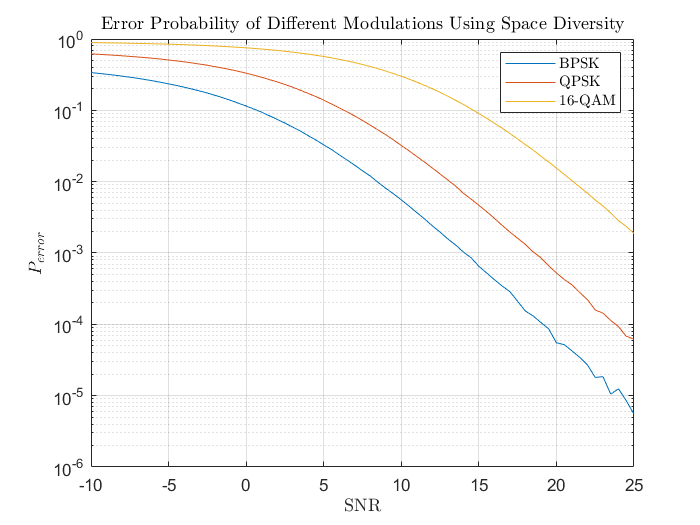

M = 16;
snrIterNum = 1;
meanPeBitList = zeros(1, length(snrBarList));

hNormal = randn(TxNum, sampleNum) + 1j * randn(TxNum, sampleNum);
HNormal = cat(3, hNormal, hNormal);

x1 = randi([0 M-1], 1, sampleNum);
x2 = randi([0 M-1], 1, sampleNum);
Xts1 = [qammod(x1, M, UnitAveragePower=true); qammod(x2, M, UnitAveragePower=true)];
Xts2 = [-conj(Xts1(2, :)); conj(Xts1(1, :))];
X = cat(3, Xts1, Xts2);

for snrBar = 10 .^ (snrBarList ./ 10)
    H = sqrt(snrBar / 2) * HNormal;
    W = sqrt(N0) .* (randn(1, sampleNum, tsNum) + 1j * randn(1, sampleNum, tsNum));
    Y = sum(X .* H, 1) + W;
    m1 = (conj(H(1, :, 1)) .* Y(1, :, 1) + H(2, :, 1) .* conj(Y(1, :, 2)))...
        ./ (abs(H(1, :, 1)) .^2 + abs(H(2, :, 1)) .^ 2);
    m2 = (conj(H(2, :, 1)) .* Y(1, :, 1) - H(1, :, 1) .* conj(Y(1, :, 2)))...
        ./ (abs(H(1, :, 1)) .^2 + abs(H(2, :, 1)) .^ 2);
    errorBits1 = symerr(qamdemod(m1, M, UnitAveragePower=true), x1);
    errorBits2 = symerr(qamdemod(m2, M, UnitAveragePower=true), x2);
    meanPeBitList(snrIterNum) = (errorBits1 + errorBits2) / (2 * sampleNum);
    snrIterNum = snrIterNum + 1;
end
semilogy(snrBarList, meanPeBitList)
grid on
title('Error Probability of Different Modulations Using Space Diversity',...
    'Interpreter', 'latex')
ylabel('$P_{error}$', 'Interpreter', 'latex')
xlabel('SNR', 'Interpreter', 'latex')
legend('BPSK', 'QPSK', '16-QAM', 'Interpreter', 'latex')